# Cruise Control: Modeling and Control Design

This example is inspired by the University of Michigan Matlab tutorials http://ctms.engin.umich.edu/

## Physical setup

Automatic **cruise control** is an excellent example of a feedback control system found in many modern vehicles. The purpose of the cruise control system is to maintain a constant vehicle speed despite external **disturbances**, such as changes in wind or road grade. This is accomplished by measuring the vehicle speed, comparing it to the desired or **reference** speed, and automatically adjusting the throttle according to a **control law**.

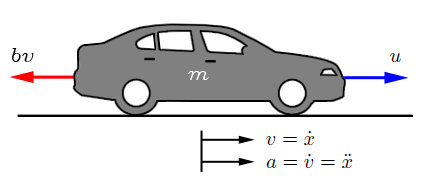

We consider here a simple model of the vehicle dynamics, shown in the free-body diagram (FBD) above. The vehicle, of mass m, is acted on by a control force, u. The force u represents the force generated at the road/tire interface. For this simplified model we will assume that we can control this force directly and will neglect the dynamics of the powertrain, tires, etc., that go into generating the force. The resistive forces, bv, due to rolling resistance and wind drag, are assumed to vary linearly with the vehicle velocity, v, and act in the direction opposite the vehicle's motion.

## System equations

With these assumptions we are left with a first-order mass-damper system. Summing forces in the x-direction and applying Newton's 2nd law, we arrive at the following system equation:


$$m\dot v + bv = u$$


Since we are interested in controlling the speed of the vehicle, the output equation is chosen as follows


$$y=v$$


## System parameters

For this example, let's assume that the parameters of the system are:

`(m)   vehicle mass          1000 kg`

`(b)   damping coefficient   50 N.s/m`

## State-space model

First-order systems have only has a single energy storage mode, in this case the kinetic energy of the car, and therefore only one state variable is needed, the velocity. The state-space representation is therefore:


$$\dot\mathbf{x} = [\dot v]= \left[\frac{-b}{m}\right][v]+\left[\frac{1}{m}\right][u] \\
y = [1][v]$$


We enter this state-space model into MATLAB using the following commands:

m = 1000;
b = 50;

A = -b/m;
B = 1/m;
C = 1;
D = 0;

cruise_ss = ss(A,B,C,D);

## Transfer function model

Taking the Laplace transform of the governing differential equation and assuming zero initial conditions, we find the transfer function of the cruise control system to be:


$$P(s) = \frac{V(s)}{U(s)}=\frac{1}{ms+b} [\frac{m/s}{N}]$$


We enter the transfer function model into MATLAB using the following commands:

s = tf('s');
P_cruise = 1/(m*s+b);

## Design requirements

- Rise time < 5 s

- Overshoot < 10%

- Steady-state error < 2%

## PID Design

We insert the PID control structure as shown below:

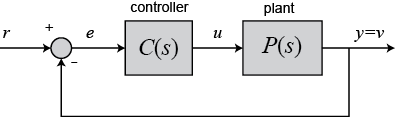

where:


$$C(s) = K_p + \frac{K_i}{s} + K_d s = \frac{K_d s^2 + K_p s + K_i}{s}$$


We can define a PID controller in MATLAB using the transfer function directly:

Kp = 1;
Ki = 1;
Kd = 1;

s = tf('s');
C = Kp + Ki/s + Kd*s


C =
 
  s^2 + s + 1
  -----------
       s
 
Continuous-time transfer function.



Alternatively, we may use MATLAB's **pid controller object** to generate an equivalent continuous time controller as follows:

C = pid(Kp,Ki,Kd)


C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1, Ki = 1, Kd = 1
 
Continuous-time PID controller in parallel form.



Note that there is no need to always employ all three gains of the PID. In fact, for a damped first order model like the one we deal here, PI control is typically sufficient. On the other hand, P-only control is likely to lead to steady-state error. 

## PI control

The closed-loop transfer function of this cruise control system with a PI controller (C = Kp + Ki/s) is:


$$T(s) = \frac{Y(s)}{R(s)}=\frac{P(s)C(s)}{1+P(s)C(s)}=\frac{K_p s +K_i}{ms^2 +(b+K_p)s+K_i}$$


For now, let Kp equal 600 and Ki equal 1 and see what happens to the response. 

% reference
r = 10;

% control parameters
Kp = 600;
Ki = 1;
C = pid(Kp,Ki);

T = feedback(C*P_cruise,1);

% time
t = 0:0.1:20;

step(r*T,t)

Undefined function or variable 't'.


axis([0 20 0 10])

Now adjust both the proportional gain, Kp, and the integral gain, Ki, to obtain the desired response. When you adjust the integral gain, Ki, we suggest you to start with a small value since a large Ki can destabilize the response. When Kp equals 800 and Ki equals 40, the step response will look like the following:

Kp = 800;
Ki = 40;
C = pid(Kp,Ki);

T = feedback(C*P_cruise,1);

step(r*T,t)
axis([0 20 0 10])

Usually choosing appropriate gains requires a trial and error process. The best way to attack this tedious process is to adjust one variable (Kp, Ki, or Kd) at a time and observe how changing one variable influences the system output.